# AAE 575 - Homework 6

clear
addpath(genpath(fileparts(which('pathfile.m'))))
interr = 'latex';
% interr = 'none';
set(groot,'defaulttextinterpreter',interr);
set(groot, 'defaultAxesTickLabelInterpreter',interr);
set(groot, 'defaultLegendInterpreter',interr);
AR = 800/600; width = 1000; height = width/AR;
set(gcf,'position',[0,0,width,height]); clear width height
c = 299792458;
RE = 6378.1e3;

## Given Locations:

% PRDU
prduECEF = [262005.750; -485513.822; 4114363.840]; %[x[m],y[m],z[m]]
prduGEO = [dms2degrees([40,25,39.69332]); -dms2degrees([86,54,39.77607]); 173.860];%[lat[deg],long[deg],eheight[m]], west means negative
% P775
p775ECEF = [254957.447; -4852054.247; 4118400.008];
p775GEO = [dms2degrees([40,28,31.40798]); -dms2degrees([86,59,31.50868]); 182.460];
% Initial Guess
gECEF = [262000; -4855100; 4114200];
gGEO = [dms2degrees([40,25,35.9453]); -dms2degrees([86,54,39.9381]); 56.9];

## Import Data: 

Day 5, Week 1848

% Corrected Psuedorange Data and PRN numbers
prangedata = load('hw6_corrected_prnage_F17.mat');
prange_corr = prangedata.prange_fix;
prnset = prangedata.prnset;
% PRDU
[ARRtime,prdu_prange,prdu_cphaseL1,prdu_cphaseL2] = importobs('prdu.dat',prnset);
% ARRtime = ARRtime*24*5*3600;
% P775
[~,p775_prange,p775_cphaseL1,p775_cphaseL2] = importobs('p775.dat',prnset);
% Ephemeris
% 1 Eccentricity:                             e
% 2 Time of Applicability(s):                 TOE
% 3 Orbital Inclination(rad):                 I_0
% 4 Rate of Right Ascen(r/s):                 OMEGA_DOT
% 5 SQRT(A) (m^1/2):                          SQRT_A
% 6 Right Ascen at TOA(rad):                  OMEGA_0
% 7 Argument of Perigee(rad):                 OMEGA
% 8 Mean Anom(rad):                           M_0
% 9 mean motion diff(r/s):                    DELTA_N
% 10 Rate of inclin (r/s):                    I_DOT
% 11 lat cosine ampl (r):                     CUC
% 12 Lat sine ampl   (r):                     CUS
% 13 radius cos ampl (m):                     CRC
% 14 radius sin ampl (m):                     CRS
% 15 inclin cos ampl(r):                      CIC
% 16 inclin sin ampl(r):                      CIS
% 17 t_gd:                                    T_GD
% 18 t_oc:                                    T_OC
% 19 Af0(s):                                  af0
% 20 Af1(s/s):                                af1
% 21 Af2(s/s/s):                              af2
for i = 1:length(prnset)
    eph(:,i) = importeph('hw6_orbits.dat',prnset(i));
end
e = eph(1,:); a = eph(5,:).^2; T_GD = eph(17,:);
sv_clocks = load('sv_clocks.mat'); sat_bias = sv_clocks.sat_tb_m;

## Problem 1:

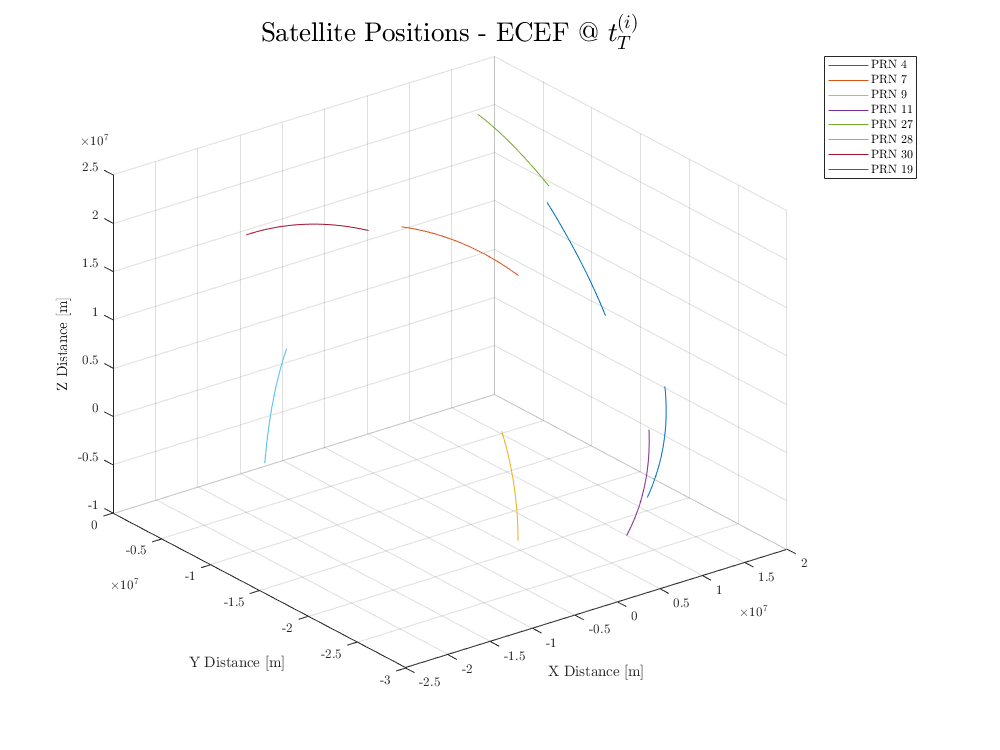

delay = p775_prange/c; 
[x4,y4,z4,GPStime,E4] = ECEF(4,eph(:,1),ARRtime,p775_prange(:,1)/c); 
[x7,y7,z7,~,E7] = ECEF(7,eph(:,2),ARRtime,p775_prange(:,2)/c);
[x9,y9,z9,~,E9] = ECEF(9,eph(:,3),ARRtime,p775_prange(:,3)/c);
[x11,y11,z11,~,E11] = ECEF(11,eph(:,4),ARRtime,p775_prange(:,4)/c);
[x27,y27,z27,~,E27] = ECEF(27,eph(:,5),ARRtime,p775_prange(:,5)/c);
[x28,y28,z28,~,E28] = ECEF(28,eph(:,6),ARRtime,p775_prange(:,6)/c);
[x30,y30,z30,~,E30] = ECEF(30,eph(:,7),ARRtime,p775_prange(:,7)/c);
[x19,y19,z19,~,E19] = ECEF(19,eph(:,8),ARRtime,p775_prange(:,8)/c);
% Calculating Satellite Positions in ECEF
E = [E4,E7,E9,E11,E27,E28,E30,E19]; clear E4 E7 E9 E11 E27 E30 E19
plot3(x4,y4,z4)
hold on
plot3(x7,y7,z7)
plot3(x9,y9,z9)
plot3(x11,y11,z11)
plot3(x27,y27,z27)
plot3(x28,y28,z28)
plot3(x30,y30,z30)
plot3(x19,y19,z19)
grid on
xlabel('X Distance [m]')
ylabel('Y Distance [m]')
zlabel('Z Distance [m]')
for i = 1:length(prnset)
    leg(i) = "PRN " + num2str(prnset(i));
end
legend([leg])
title('Satellite Positions - ECEF @ $t_{T}^{(i)}$','FontSize',20)
hold off

## Problem 2:

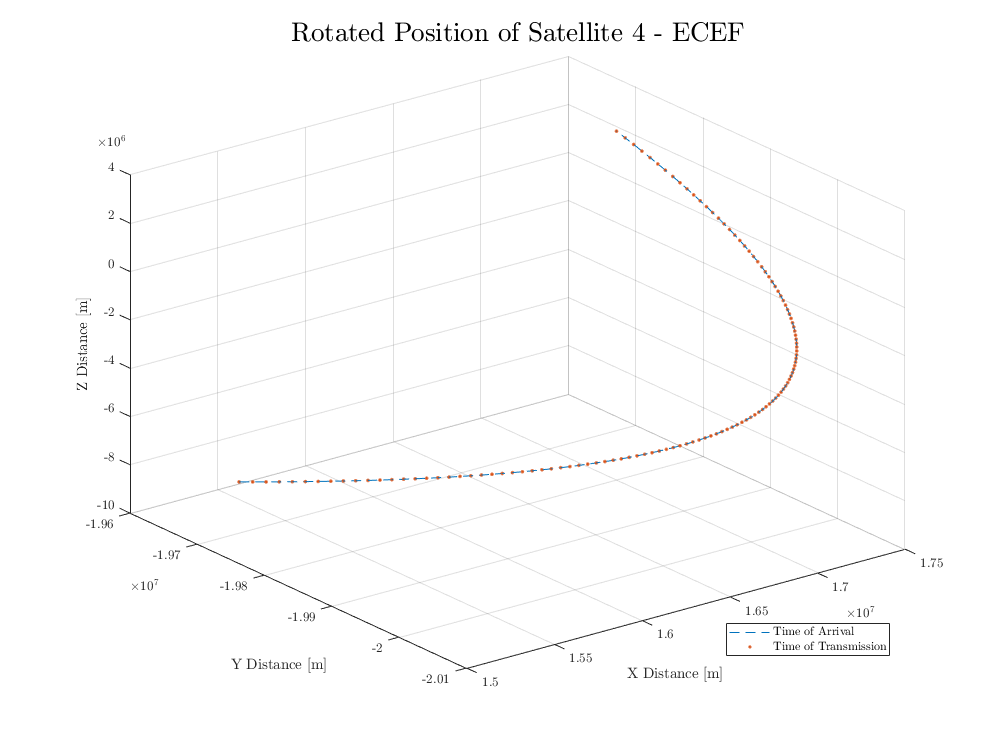

[pos4_R,pos4_T] = rotPos(x4,y4,z4,delay(:,1));
[pos7_R,pos7_T] = rotPos(x7,y7,z7,delay(:,2));
[pos9_R,pos9_T] = rotPos(x9,y9,z9,delay(:,3));
[pos11_R,pos11_T] = rotPos(x11,y11,z11,delay(:,4));
[pos27_R,pos27_T] = rotPos(x27,y27,z27,delay(:,5));
[pos28_R,pos28_T] = rotPos(x28,y28,z28,delay(:,6));
[pos30_R,pos30_T] = rotPos(x30,y30,z30,delay(:,7));
[pos19_R,pos19_T] = rotPos(x19,y19,z19,delay(:,8));
% Rotating sat positions due to travel delay
sat_pos_R = {pos4_R;pos7_R;pos9_R;pos11_R;pos27_R;pos28_R;pos30_R;pos19_R};
sat_pos_T = {pos4_T;pos7_T;pos9_T;pos11_T;pos27_T;pos28_T;pos30_T;pos19_T};
plot3(pos4_R(:,1),pos4_R(:,2),pos4_R(:,3),'--')
hold on
plot3(pos4_T(:,1),pos4_T(:,2),pos4_T(:,3),'.')
legend('Time of Arrival','Time of Transmission','Location',"best")
title('Rotated Position of Satellite 4 - ECEF','FontSize',20)
grid on
xlabel('X Distance [m]')
ylabel('Y Distance [m]')
zlabel('Z Distance [m]')
hold off

## Problem 3:

alpha = [0.01397, 0.022352, -0.11921 -0.11921]*1e-6;
beta = [110590 163840 -65536 -524290];
% converting ecef coordinates to az el
[az4,el4,~] = ecef2aer(pos4_R(:,1),pos4_R(:,2),pos4_R(:,3),gGEO(1),gGEO(2),gGEO(3),wgs84Ellipsoid);
[az7,el7,~] = ecef2aer(pos7_R(:,1),pos7_R(:,2),pos7_R(:,3),gGEO(1),gGEO(2),gGEO(3),wgs84Ellipsoid);
[az9,el9,~] = ecef2aer(pos9_R(:,1),pos9_R(:,2),pos9_R(:,3),gGEO(1),gGEO(2),gGEO(3),wgs84Ellipsoid);
[az11,el11,~] = ecef2aer(pos11_R(:,1),pos11_R(:,2),pos11_R(:,3),gGEO(1),gGEO(2),gGEO(3),wgs84Ellipsoid);
[az27,el27,~] = ecef2aer(pos27_R(:,1),pos27_R(:,2),pos27_R(:,3),gGEO(1),gGEO(2),gGEO(3),wgs84Ellipsoid);
[az28,el28,~] = ecef2aer(pos28_R(:,1),pos28_R(:,2),pos28_R(:,3),gGEO(1),gGEO(2),gGEO(3),wgs84Ellipsoid);
[az30,el30,~] = ecef2aer(pos30_R(:,1),pos30_R(:,2),pos30_R(:,3),gGEO(1),gGEO(2),gGEO(3),wgs84Ellipsoid);
[az19,el19,~] = ecef2aer(pos19_R(:,1),pos19_R(:,2),pos19_R(:,3),gGEO(1),gGEO(2),gGEO(3),wgs84Ellipsoid);
az = [az4,az7,az9,az11,az27,az28,az30,az19]; el = [el4,el7,el9,el11,el27,el28,el30,el19];
clear az4 az7 az9 az11 az27 az28 az30 az19 el4 el7 el9 el11 el27 el28 el30 el19
% using klobuchar model to calculate ionospheric delay
for i = 1:length(prnset)
    % for i = 1
    [iono(:,i)] = klobmodel(gGEO(1),gGEO(2),az(:,i),el(:,i),ARRtime,alpha,beta); % delay in sec
end

Error using klobmodel
Too many input arguments.

plot(ARRtime,iono)
title("Ionospheric Delay - Klobuchar Model",'FontSize',20)
xlabel('Receiver Time, s')
ylabel('Delay, m')
grid on
legend(leg)

## Problem 4:

RH = .4; T = 292.85; P0 = 983.1;
% using saastamoinen model and chao mapping to get tropospheric delay
for i = 1:length(prnset)
    trop(:,i) = saastamoinen(RH,T,P0,gGEO(1),gGEO(2),gGEO(3),az(:,i),el(:,i)); % delay in sec
end
plot(ARRtime,trop)
title("Tropospheric Delay - Saastamoinen - Chao Mapping Functions",'FontSize',20)
xlabel('Receiver Time, s')
ylabel('Delay, m')
grid on
legend(leg)

## Problem 5:

% calculating relativity and differential group delay
F = -4.442807633e-10;
rel = F*e.*eph(5,:).*sin(E);
% calculating corrected pseudorange
prange_cr = p775_prange - c*(T_GD-rel-sat_bias)- iono-trop;
plot(ARRtime,prange_cr-prange_corr)
title("Corrected Pseudorange Error (Calculated vs Given)",'FontSize',20)
xlabel('Receiver Time, s')
ylabel('Error, m')
grid on
legend(leg,'Location',"best")
plot(ARRtime,prange_cr)
title("Corrected Pseudorange",'FontSize',20)
xlabel('Receiver Time, s')
ylabel('Error, m')
grid on
legend(leg,'Location',"best")
clear x4 x7 x9 x11 x27 x28 x30 x19 y4 y7 y9 y11 y27 y28 y30 y19 z4 z7 z9 z11 z27 z28 z30 z19 ...
    pos4_R pos7_R pos9_R pos11_R pos27_R pos28_R pos30_R pos19_R ...
    pos4_T pos7_T pos9_T pos11_T pos27_T pos28_T pos30_T pos19_T

## Problem 6:

sat_load = load('epehemeris.mat');
for w = 1:length(prnset)
    sat_pos{w} = [sat_load.XsvE(:,w),sat_load.YsvE(:,w),sat_load.ZsvE(:,w)];
end

y = cell(120,1);
H = cell(120,1);
delR = cell(120,1);
XHAT = cell(120,1);
Xstar = cell(120,1);

% iterative process for calculating navigation solution for all time steps
for p = 1:length(GPStime)
    Xstar{p} = [gECEF;1];
end
for i = 1:length(GPStime) % for each time step
    delta = 100;
    %%%% Iterated Part
    k = 1;
    while delta > 0.05
        if k > 1
            old = delR{i};
        end
        for j = 1:length(prnset)
            range_comp = norm(sat_pos{j}(i,:) - Xstar{i}(1:3)');
            y{i}(j,:) = (prange_corr(i,j) - range_comp - Xstar{i}(4)); %1
            H{i}(j,:) = [(Xstar{i}(1:3)'-sat_pos{j}(i,:))/range_comp,1]; %2
        end
        delR{i} = ((H{i}'*H{i})\H{i}'*y{i});
        XHAT{i} = Xstar{i}+delR{i};
        Xstar{i} = XHAT{i};
        if k > 1
            delta = norm(delR{i}(1:3));
        end
        k = k+1;
    end
end

## Problem 8:

lat = zeros(size(GPStime)); long = zeros(size(GPStime)); alt = zeros(size(GPStime));
estECEF = zeros(length(GPStime),3);
% calculating geodetic coordinates from ECEF
for i = 1:length(XHAT)
    %     LLA_est(i,:) = ecef2lla(XHAT{i}(1:3)', 'WGS84');
    [lat(i),long(i),alt(i)] = ECEF2GEODETIC(XHAT{i});
    estECEF(i,:) = XHAT{i}(1:3);
end
% error in navigation solution
estGEO = [lat long alt];
errorECEF =  estECEF - p775ECEF';
errorGEO =  estGEO - p775GEO';
plot(ARRtime,errorECEF)
legend('X Error','Y Error','Z Error')
xlabel('Receiver Time, s')
ylabel('Error, m')
title('Error in Navigation Solution (ECEF)','FontSize',15)
grid on
plot3(estECEF(:,1),estECEF(:,2),estECEF(:,3))
grid on
title('Navigation Solution - ECEF')
xlabel('X Distance [m]')
ylabel('Y Distance [m]')
zlabel('Z Distance [m]')
hold on
plot3(p775ECEF(1),p775ECEF(2),p775ECEF(3),'X','MarkerSize',30)
hold off
subplot(3,1,1)
plot(ARRtime,estGEO(:,1))
grid on
ylabel('Degrees, $\circ$')
title('Geodetic Latitude','FontSize',15)
subplot(3,1,2)
plot(ARRtime,estGEO(:,2))
grid on
ylabel('Degrees, $\circ$')
title('Geodetic Longitude','FontSize',15)
subplot(3,1,3)
plot(ARRtime,estGEO(:,3))
ylabel('Error, m')
xlabel('Receiver Time, s')
grid on
title('Ellipsoidal Height, m','FontSize',15)
sgtitle('Navigation Solution - Geodetic','FontSize',20)
subplot(2,1,1)
plot(ARRtime,errorGEO(:,1:2))
grid on
legend('Latitude Error','Longitude Error','Location',"best")
ylabel('Error, $\circ$')
title('Latitude and Longitude Error','FontSize',15)
subplot(2,1,2)
plot(ARRtime,errorGEO(:,3))
ylabel('Error, m')
xlabel('Receiver Time, s')
grid on
title('Ellipsoidal Height Error','FontSize',15)
sgtitle('Error in Navigation Solution (Geodetic)','FontSize',20)

## Problem 9:

GDOP = zeros(length(XHAT),1); PDOP = zeros(length(XHAT),1); TDOP = zeros(length(XHAT),1);
HDOP = zeros(length(XHAT),1); VDOP = zeros(length(XHAT),1); Tr = {};
% calculating DOP values
for i = 1:length(XHAT)
    [GDOP(i),PDOP(i),TDOP(i),HDOP(i),VDOP(i),PPP{i}] = precdil(XHAT{i},H{i},estGEO(i,:));
end
DOPs = [GDOP,PDOP,TDOP,HDOP,VDOP];
figure
plot(ARRtime,DOPs)
xlabel('Receiver Time, s')
ylabel('Dillution of Precision')
title('Dilution of Precision over Time')
legend('GDOP','TDOP','PDOP','HDOP','VDOP','Location',"eastoutside")
grid on

## Problem 10:

% calculating dop values statistically
rss3D = sqrt(std(errorECEF(:,1)).^2+std(errorECEF(:,2)).^2+std(errorECEF(:,3)).^2)
rms3D = sqrt(1/size(errorECEF,1) * sum(errorECEF(:,1).^2+errorECEF(:,2).^2+errorECEF(:,3).^2))
[xE,yN,zU] = ecef2enu(estECEF(:,1),estECEF(:,2),estECEF(:,3),p775GEO(1),p775GEO(2),p775GEO(3),wgs84Ellipsoid);
xEstd = std(xE)
yNstd = std(yN)
hPosstd = sqrt(xEstd^2+yNstd^2)
vPosstd = sqrt(std(zU)^2)